function [dx, dy, theta] = pract1(wid, wdd, tsim, Tm)
    % Parámetros del sistema
    d = 0.8;      % Distancia entre ruedas (m)
    R = 0.1;      % Radio de las ruedas (m)
    v_max = 15;   % Velocidad máxima permitida (rad/s)
    Tw = 0.12;    % Constante de tiempo de la rueda
    tam = length(wid);  % Número de elementos en wid (tamaño del bucle)
    a = 1 / Tw;   % Parámetro para el filtrado exponencial

    % Inicialización de variables con ceros
    wi = zeros(1, tam + 1); % Velocidad angular izquierda filtrada
    wd = zeros(1, tam + 1); % Velocidad angular derecha filtrada
    v = zeros(1, tam);      % Velocidad lineal del robot
    w = zeros(1, tam);      % Velocidad angular del robot
    ds = zeros(1, tam);     % Desplazamiento en cada paso
    theta = zeros(1, tam);  % Ángulo girado en cada paso
    dx = zeros(1, tam);     % Desplazamiento en el eje X
    dy = zeros(1, tam);     % Desplazamiento en el eje Y

    % Bucle para calcular la cinemática del robot
    for i = 1:tam
        % Filtrado exponencial de las velocidades angulares de las ruedas
        wi(i+1) = exp(-a * Tm) * wi(i) + (1 - exp(-a * Tm)) * wid(i);
        wd(i+1) = exp(-a * Tm) * wd(i) + (1 - exp(-a * Tm)) * wdd(i);
        
        % Limitación de velocidad máxima
        wi(i+1) = min(wi(i+1), v_max);
        wd(i+1) = min(wd(i+1), v_max);

        % Cálculo de la velocidad lineal y angular del robot
        v(i) = (wi(i) + wd(i)) * R / 2;  % Promedio de velocidades de las ruedas
        w(i) = (wd(i) - wi(i)) * R / d;  % Diferencia entre ruedas dividida por la distancia entre ellas

        % Cálculo de desplazamientos y ángulos
        ds(i) = v(i) * tsim(i);     % Distancia recorrida en este paso
        theta(i) = w(i) * tsim(i);  % Cambio en el ángulo del robot
        dx(i) = cos(theta(i)) * ds(i);  % Desplazamiento en X
        dy(i) = sin(theta(i)) * ds(i);  % Desplazamiento en Y
    end
end


% Definir los valores de entrada
j=10;
wid = 5*ones(j);   % Velocidad angular deseada para la rueda izquierda
wdd = 5*ones(j);   % Velocidad angular deseada para la rueda derecha
tsim = ones(j);   % Intervalo de tiempo constante de 1s en cada paso
Tm = 0.12;                % Constante de tiempo del sistema

% Llamar a la función y obtener resultados
[dx, dy, theta] = pract1(wid, wdd, tsim, Tm);

% Mostrar resultados
disp('dx ='), disp(dx)

dx =
         0    0.3161    0.4323    0.4751    0.4908    0.4966    0.4988    0.4995    0.4998    0.4999



disp('dy ='), disp(dy)

dy =
     0     0     0     0     0     0     0     0     0     0



disp('theta ='), disp(theta)

theta =
     0     0     0     0     0     0     0     0     0     0



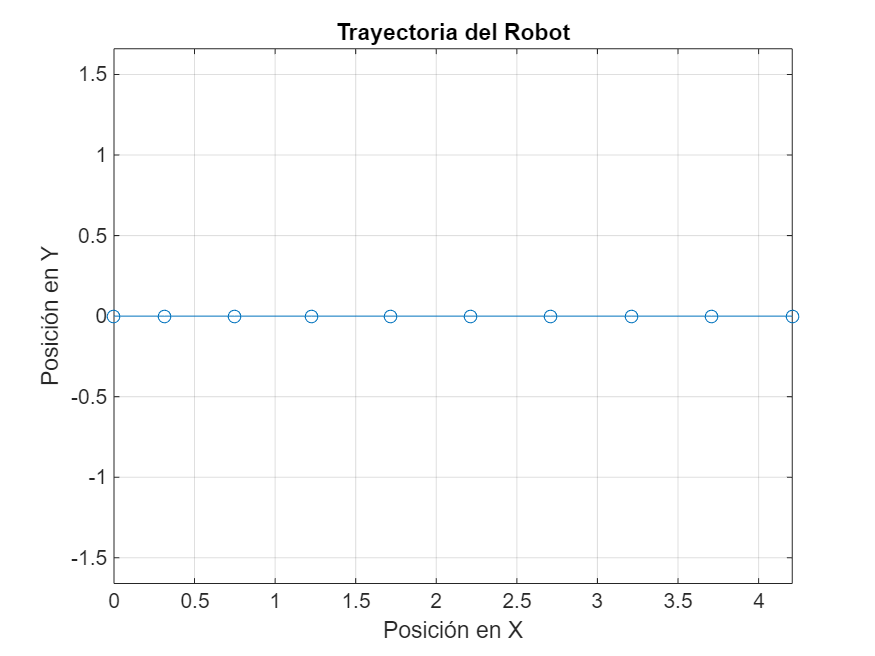


% Graficar la trayectoria
plot(cumsum(dx), cumsum(dy), '-o');
xlabel('Posición en X');
ylabel('Posición en Y');
title('Trayectoria del Robot');
grid on;
axis equal;


% Definir los valores de entrada
wid = 5*ones(j);   % Velocidad angular deseada para la rueda izquierda
wdd = ones(j);   % Velocidad angular deseada para la rueda derecha
tsim = ones(j);   % Intervalo de tiempo constante de 1s en cada paso
Tm = 0.12;                % Constante de tiempo del sistema

% Llamar a la función y obtener resultados
[dx, dy, theta] = pract1(wid, wdd, tsim, Tm);

% Mostrar resultados
disp('dx ='), disp(dx)

dx =
         0    0.1802    0.2355    0.2535    0.2597    0.2620    0.2628    0.2631    0.2632    0.2633



disp('dy ='), disp(dy)

dy =
         0   -0.0589   -0.1087   -0.1304   -0.1388   -0.1420   -0.1431   -0.1436   -0.1437   -0.1438



disp('theta ='), disp(theta)

theta =
         0   -0.3161   -0.4323   -0.4751   -0.4908   -0.4966   -0.4988   -0.4995   -0.4998   -0.4999



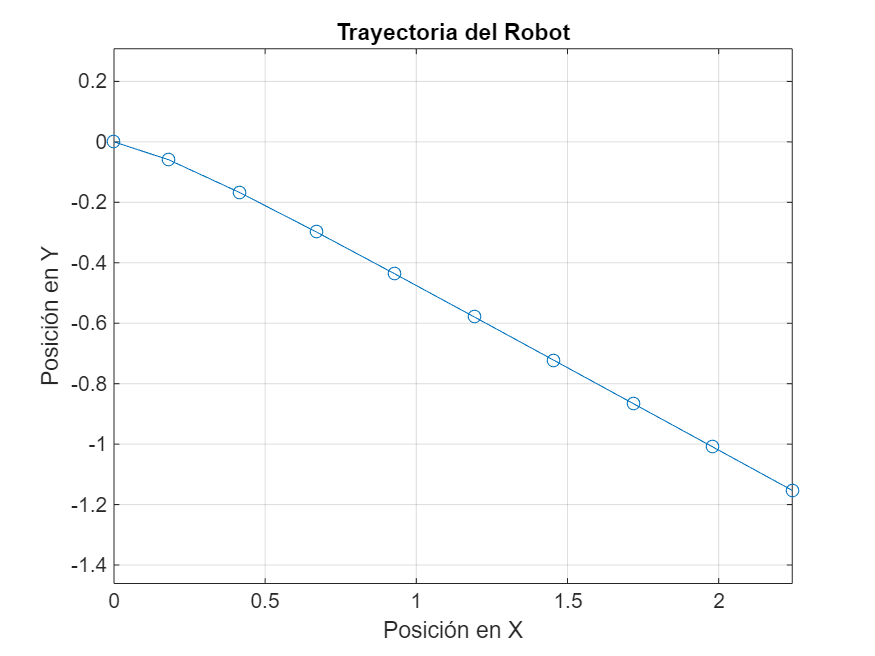


% Graficar la trayectoria
plot(cumsum(dx), cumsum(dy), '-o');
xlabel('Posición en X');
ylabel('Posición en Y');
title('Trayectoria del Robot');
grid on;
axis equal;


% Definir los valores de entrada
wid = ones(j);   % Velocidad angular deseada para la rueda izquierda
wdd = 5*ones(j);   % Velocidad angular deseada para la rueda derecha
tsim = ones(j);   % Intervalo de tiempo constante de 1s en cada paso
Tm = 0.12;                % Constante de tiempo del sistema

% Llamar a la función y obtener resultados
[dx, dy, theta] = pract1(wid, wdd, tsim, Tm);

% Mostrar resultados
disp('dx ='), disp(dx)

dx =
         0    0.1802    0.2355    0.2535    0.2597    0.2620    0.2628    0.2631    0.2632    0.2633



disp('dy ='), disp(dy)

dy =
         0    0.0589    0.1087    0.1304    0.1388    0.1420    0.1431    0.1436    0.1437    0.1438



disp('theta ='), disp(theta)

theta =
         0    0.3161    0.4323    0.4751    0.4908    0.4966    0.4988    0.4995    0.4998    0.4999



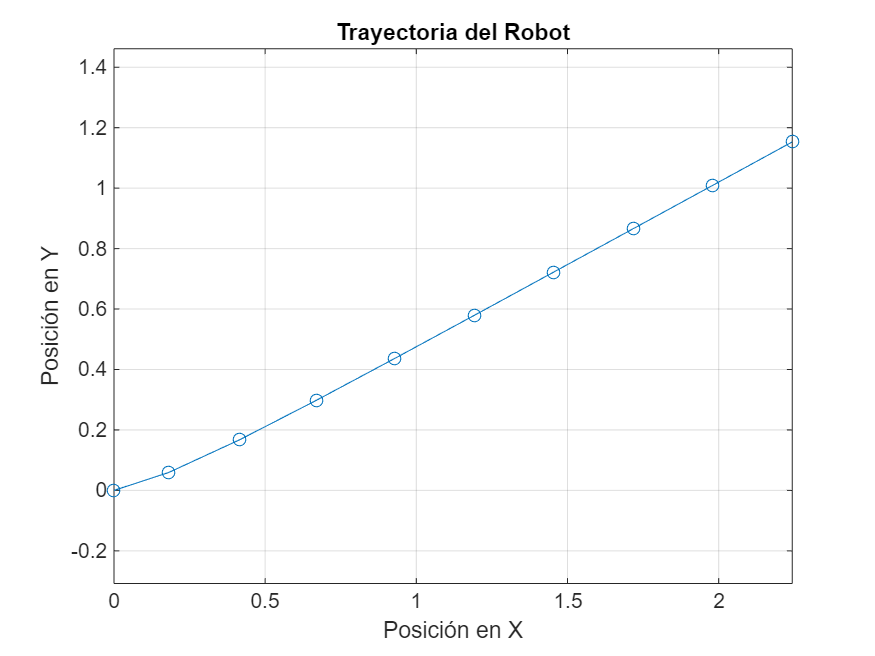


% Graficar la trayectoria
plot(cumsum(dx), cumsum(dy), '-o');
xlabel('Posición en X');
ylabel('Posición en Y');
title('Trayectoria del Robot');
grid on;
axis equal;

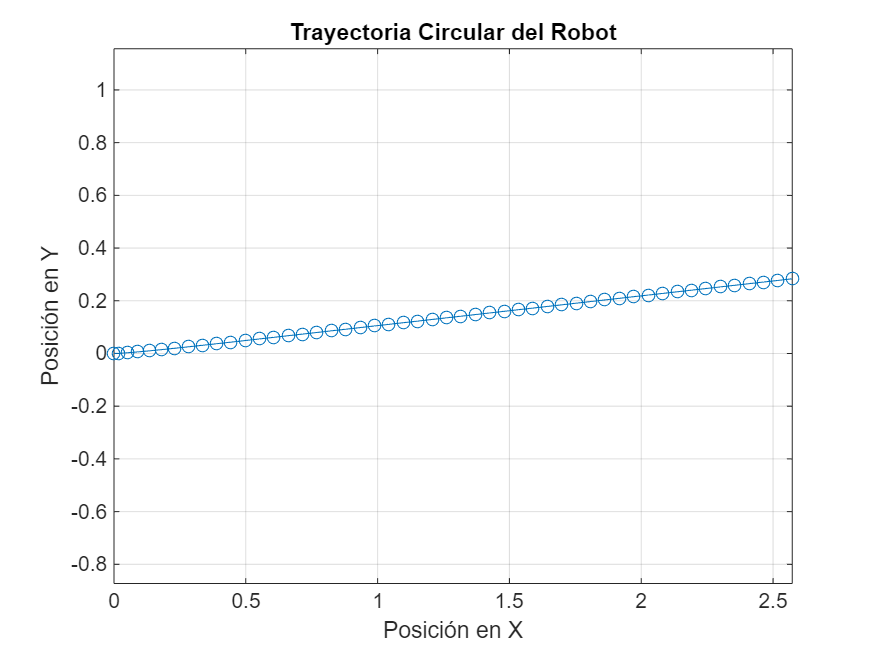

n = 50;  % Número de pasos de simulación
wid = ones(1, n) ;   % Velocidad angular izquierda (constante)
wdd = ones(1, n) * 10;  % Velocidad angular derecha (constante)
tsim = ones(1, n) * 0.1;  % Intervalos de tiempo constantes de 0.1s
Tm = 0.05;  % Constante de tiempo del sistema
[dx, dy, theta] = pract1(wid, wdd, tsim, Tm);

% Graficar la trayectoria
plot(cumsum(dx), cumsum(dy), '-o');
xlabel('Posición en X');
ylabel('Posición en Y');
title('Trayectoria Circular del Robot');
grid on;
axis equal;